# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

姓名：   王晨晖      学号：   24307163    专业：   电子信息工程  

## 实验三 离散傅里变换及其应用

## 一、实验目的

- 掌握求解周期序列傅里叶级数变换DFS和逆变换IDFS的方法

- 掌握进行离散傅里叶变换DFT和逆变换IDFT的方法

- 掌握MATLAB进行离散傅里叶变换性质分析时程序编写的方法

- 掌握使用快速傅里叶变换（FFT）计算有限长序列信号频谱方法 

- 了解MATLAB进行时域抽样与信号重建方法

- 掌握采样频率的确定方法和内插公式的编程

- 掌握MATLAB进行频域抽样与恢复时程序编写方法

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

（根据具体实验内容和要求，简述所涉及的数字信号处理基本概念、理论知识和实验原理，对基本概念和理论进行解释、列出必要的公式）

**            1.DTFT（离散时间傅里叶变换）**：将非周期无限长离散序列映射为连续周期的数字频谱。

**            2.DFS（离散傅里叶级数）**：将周期离散序列分解为离散频率分量的傅里叶级数形式，频谱同样呈周期离散特性。

**            3.DFT（离散傅里叶变换）**：对有限长离散序列做频域等间隔采样，得到有限长离散频谱，是工程中最常用的频域分析方法

            4. **IDTFT（逆离散时间傅里叶变换）**：由连续周期数字频谱还原出对应的非周期无限长离散序列。

            5. **IDFS（逆离散傅里叶级数）**：由周期离散频谱重构原始周期离散时间序列。

            6. **IDFT（逆离散傅里叶变换）**：由有限长离散频谱恢复出原始有限长离散时间序列。

            7.**DFS 与 DFT**：将有限长序列周期延拓得到周期序列，其 DFS 主值区间序列即为原序列的 DFT。

**            8.DTFT 与 DFT**：有限长序列的 DFT，是对该序列 DTFT 在一个周期内做等间隔采样得到的结果。

**            9.DFS 与 DTFT**：周期离散序列的 DFS 系数，是其单周期序列 DTFT 在谐波频率点上的采样值

            10.**FFT**：快速傅里叶变换，是高效计算 DFT 的快速算法，能大幅减少运算量，结果与 DFT 完全一致。

**频域补零对于时域的影响**`；`频域补零是在离散频谱序列的末端补充若干零值，以此增加频域总点数；根据傅里叶变换的对偶性质，频域补零等效于在时域对原序列进行插值加密，能够让时域波形曲线变得更加平滑、细腻，提升时域波形的视觉分辨率，但该操作并未增加信号的有效信息，也无法改善频率分辨率，不能区分原本相近的频率分量。

**讨论原时域信号不失真地由频域抽样恢复的条件**`；`离散序列由频域抽样实现时域无失真恢复，需满足**频域抽样定理**：若长度为N的有限长时域序列x[n]，对其 DTFT 在一个周期[0,2π)内做M点等间隔频域抽样，当抽样点数M≥N时，可由频域抽样序列无失真恢复原时域序列；若M<N，则会发生时域混叠，无法完整还原原始信号。本质上，频域抽样对应时域周期延拓，只有频域抽样点数不少于原序列长度，各周期延拓的时域波形才不会相互重叠，进而实现无失真重建。

## 四、实验所用MATLAB函数

（列出实验中需要用到的MATLAB函数并简述其功能）

            **fft(x)**：对有限长序列 x 执行快速傅里叶变换，输出长度与 x 相同，结果为 x 的 DFT。

**            fft(x,N)**：对 x 补零或截断为长度 N，再计算 N 点 DFT，默认在序列的尾端补零。

            **ifft(x)**：快速逆离散傅里叶变换（IDFT），与 fft 互逆，可由频域序列恢复时域序列，支持指定点数补零 / 截断运算。

## 五、实验内容、方法、代码与结果

### **题目1**：已知周期序列的主值$x\left(n\right)=\left\lbrack 7,6,5,3,4,2\right\rbrack$,求$x\left(n\right)$周期重复次数为3次时的DFS变换$\tilde{x}(k)$（注意$w_k = \exp(-j \cdot 2\pi / N \cdot k),N=6,k=0,1,2...17$；n的取值可以从0到5，也可以从0到17，比较二者差异，结果应该差3倍，相当于重复计算了3次），并在基础上再计算得到$\tilde{x}(k)$的IDFS。要求根据DFS和IDFS的定义编程，不能调用库函数。

**（1）画出原信号序列的主值和周期序列的图形**`；`

**（2）画出序列傅里叶变换对应的**$\vert\tilde{x}(k)\vert$和$arg\tilde{x}(k)$的图形`。`

**   (3）画出**$\tilde{x}(k)$的IDFS变换的图形`。`

**解答1**：

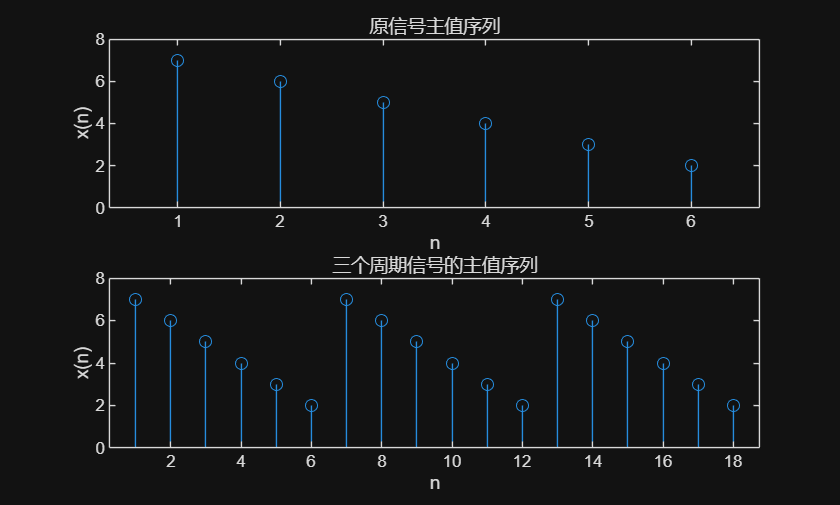

% Insert your code here
x = [7 6 5 4 3 2];
xn = [x x x];
N = length(x);
n = 0:length(xn)-1;
k = 0:3*N-1;
wk = exp(-1j*2*pi/N);
%for i = 1:N
%    X(i) = sum(x.*wk(i).^(n*k));
%end
%for i = 1:length(k)
%    XN(i) = sum(xn.*wk(i).^(0:length(xn)-1));
%end
figure;
subplot(2,1,1);
stem(x);
title('原信号主值序列');
xlabel('n');
ylabel('x(n)');
subplot(2,1,2);
stem(xn);
title('三个周期信号的主值序列');
xlabel('n');
ylabel('x(n)');

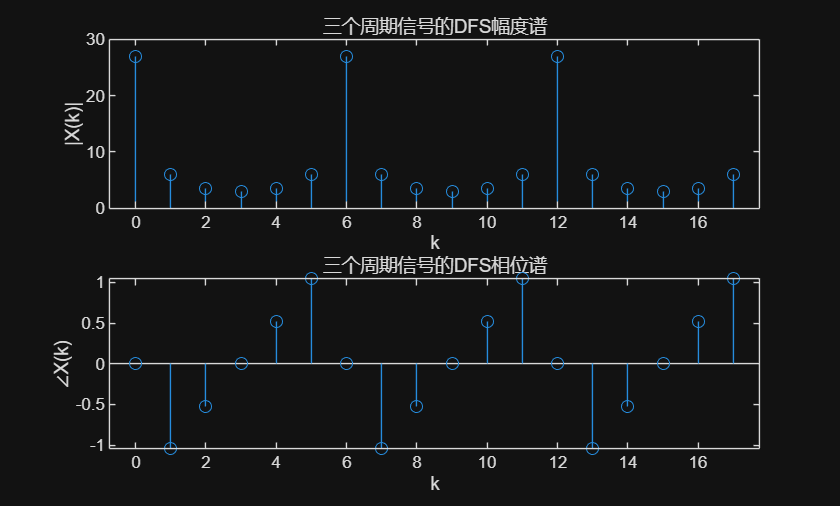

XN = 1/3*xn*wk.^(n'*k);
X = x*wk.^((0:5)'*k);
figure;
subplot(2,1,1);
stem(k,abs(XN));
title('三个周期信号的DFS幅度谱');
xlabel('k');
ylabel('|X(k)|');
subplot(2,1,2);
stem(k,angle(XN));
title('三个周期信号的DFS相位谱');
xlabel('k');
ylabel('∠X(k)');

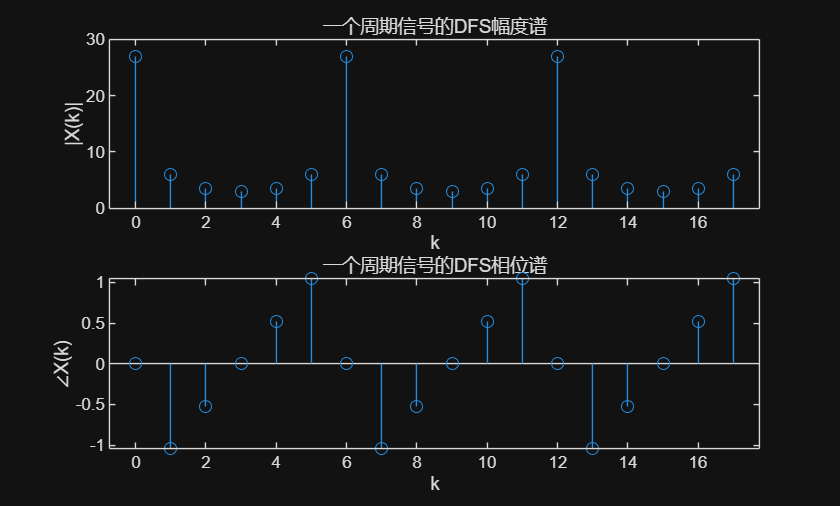

figure;
subplot(2,1,1);
stem(k,abs(X));
title('一个周期信号的DFS幅度谱');
xlabel('k');
ylabel('|X(k)|');
subplot(2,1,2);
stem(k,angle(X));
title('一个周期信号的DFS相位谱');
xlabel('k');
ylabel('∠X(k)');

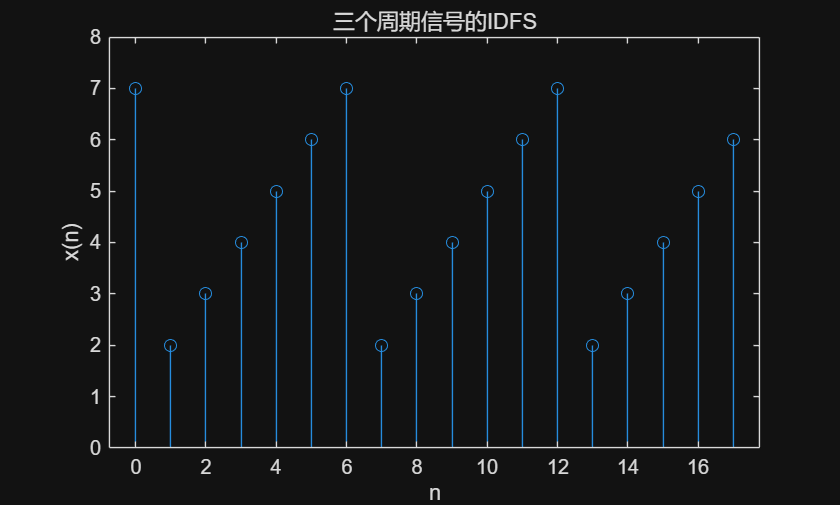

xn_IDFS = 1/N/3*XN*wk.^(k'*n);
figure;
stem(n,real(xn_IDFS));
title('三个周期信号的IDFS');
xlabel('n');
ylabel('x(n)');

### **题目2**：已知有限长序列$x\left(n\right)=\left\lbrack 7,5,6,4,3,2\right\rbrack$，求$x\left(n\right)$的DFT和IDFT。要求如下，请根据DFT和IDFT的定义编程，不能调用库函数。

**①画出序列傅里叶变换对应的**$\left|X\left(k\right)\right|$和$\arg \left\lbrack X\left(k\right)\right\rbrack$的图形`；`

**②画出原信号与傅里叶逆变换IDFT**$\left\lbrack X\left(k\right)\right\rbrack$的图形进行比较`。`

**解答2**：

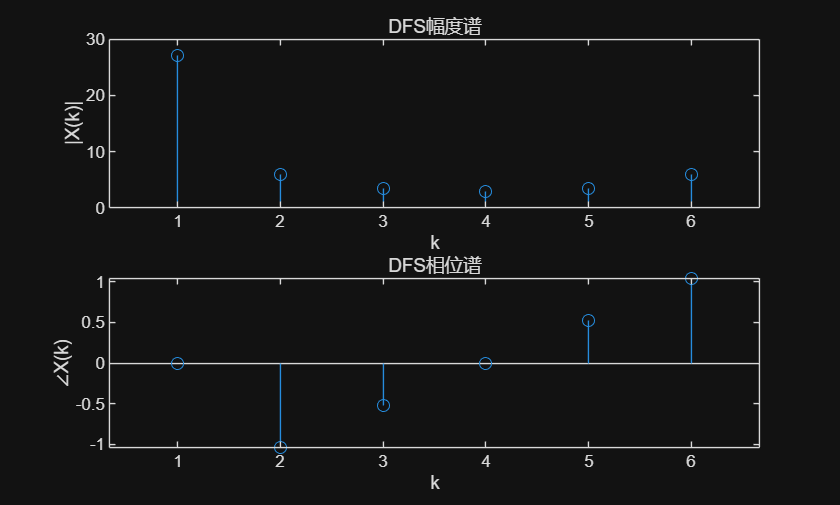

% Insert your code here
xn = [7 6 5 4 3 2];
N = length(xn);
X_DFT = zeros(1,N);
for k = 0:N-1
    sum_val = 0;
    for i = 0:N-1
        sum_val = sum_val + xn(i+1) * exp(-1j * 2 * pi * k * i / N);
    end
    X_DFT(k+1) = sum_val;
end
figure;
subplot(2,1,1);
stem(abs(X_DFT));
title('DFS幅度谱');
xlabel('k');
ylabel('|X(k)|');
subplot(2,1,2);
stem(angle(X_DFT));
title('DFS相位谱');
xlabel('k');
ylabel('∠X(k)');

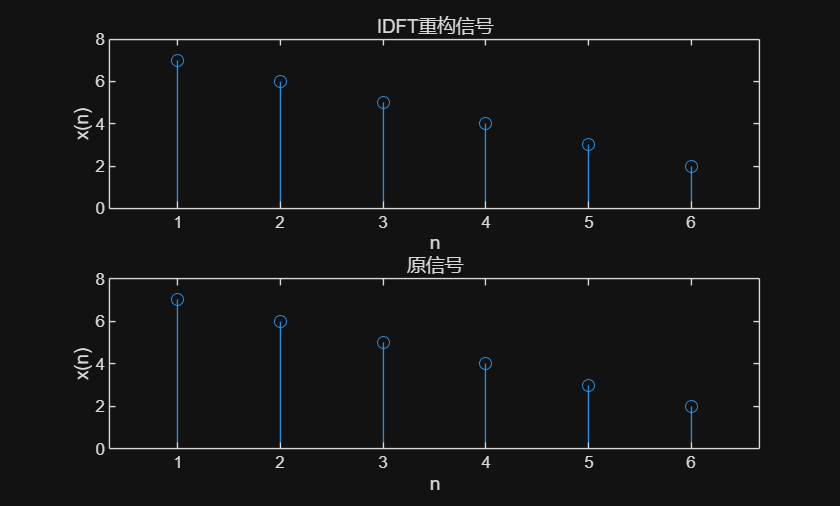

X_IDFT = zeros(1,N);
for n = 0:N-1
    sum_val = 0;
    for k = 0:N-1
        sum_val = sum_val + X_DFT(k+1) * exp(1j * 2 * pi * k * n / N);
    end
    X_IDFT(n+1) = sum_val / N;
end
figure;
subplot(2,1,1);
stem(real(X_IDFT));
title('IDFT重构信号');
xlabel('n');
ylabel('x(n)');
subplot(2,1,2);
stem(xn);
title('原信号');
xlabel('n');
ylabel('x(n)');

### **题目3**：求$x\left(n\right)=\left\lbrack 7,6,5,4,3,2\right\rbrack ,0\le n\le 5$的DTFT，将$\left\lbrack -2\pi ,2\pi \right\rbrack$区间分成2000份。要求如下，请根据DTFT的定义进行求解。

**①画出原信号**`；`

**②画出序列傅里叶变换对应的**$X(e^{j\omega})$和$arg[X(e^{j\omega})]$的图形`。`

**③求有限长序列**$x\left(n\right)=\left\lbrack 7,6,5,4,3,2\right\rbrack ,N=100$时的DFT，并与DTFT的结果进行比较`；`

**解答3**：

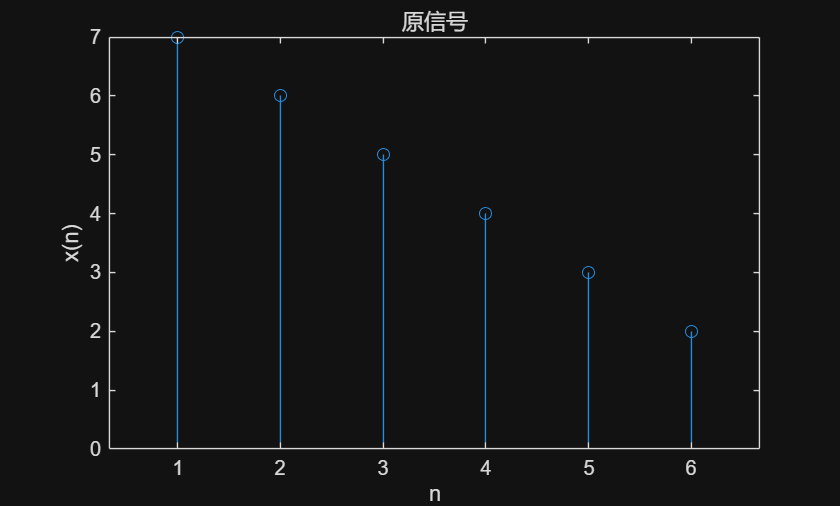

% Insert your code here
xn = [7 6 5 4 3 2];
n = 0:length(xn)-1;
w = linspace(-2*pi, 2*pi, 2000);
X_DTFT = zeros(size(w));
for i = 1:length(w)
    X_DTFT(i) = sum(xn.*exp(-1j*w(i)*n));
end
figure;
stem(xn);
title('原信号');
xlabel('n');
ylabel('x(n)');

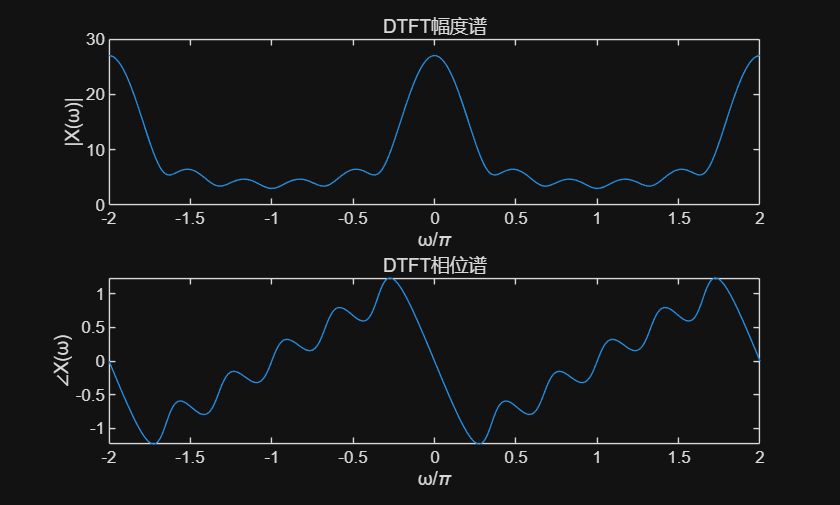

figure;
subplot(2,1,1);
plot(w/pi,abs(X_DTFT));
title('DTFT幅度谱');
xlabel('ω/\pi');
ylabel('|X(ω)|');
subplot(2,1,2);
plot(w/pi,angle(X_DTFT));
title('DTFT相位谱');
xlabel('ω/\pi');
ylabel('∠X(ω)');

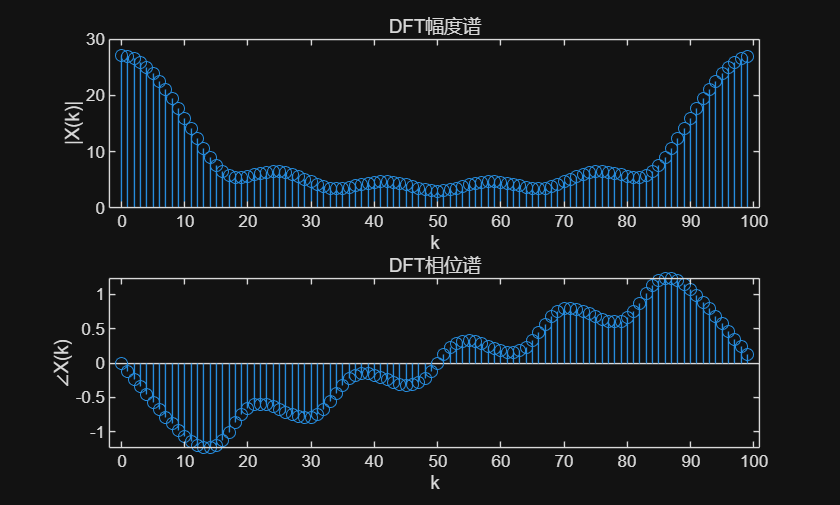

N = 100;
k = 0:N-1;
wk = exp(-1j*2*pi/N);

X_DFT = xn*wk.^((0:5)'*k);

figure;
subplot(2,1,1);
stem(k,abs(X_DFT));
title('DFT幅度谱');
xlabel('k');
ylabel('|X(k)|');
subplot(2,1,2);
stem(k,angle(X_DFT));
title('DFT相位谱');
xlabel('k');
ylabel('∠X(k)');

### **题目4**：已知有限长序列$x\left(n\right)=\left\lbrack 1,0\ldotp 5,0,0\ldotp 5,1,1,0\ldotp 5,0\right\rbrack$。要求：

### **①假定采样频率**$F_a =20\textrm{Hz}$，DFT点数分别取8、32和64，使用FFT来计算其幅度频谱和相位频谱（画图横轴用模拟频率），说明时域补零对于频域的影响`。`

### **②调用IFFT求上述8点DFT所得频谱的逆变换，其中，求逆变换的点数分别为8、32、64（注意补零的位置应该在高频位置，对于FFT得到的谱，应该在向量最中间位置补零，即在高频部分补零），说明这种频域补零对于时域的影响**`；`

**解答4**：

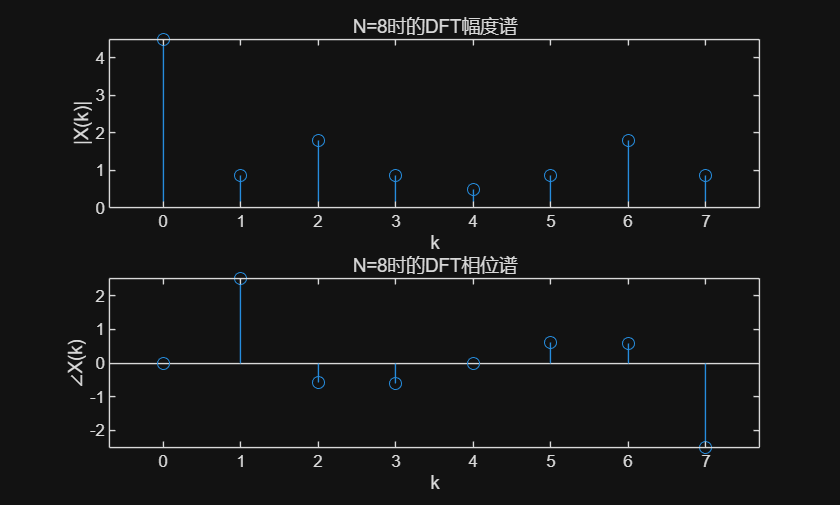

% Insert your code here
xn = [1 0.5 0 0.5 1 1 0.5 0];
fa = 20;
N1 = 8;
N2 = 32;
N3 = 64;
x1n = xn;
x2n = [x1n zeros(1,N2-N1)];
x3n = [x1n zeros(1,N3-N1)];
%计算fft
X1k = fft(x1n);
X2k = fft(x2n);
X3k = fft(x3n);
figure;
subplot(2,1,1);
stem(0:N1-1,abs(X1k));
title('N=8时的DFT幅度谱');
xlabel('k');
ylabel('|X(k)|');
subplot(2,1,2);
stem(0:N1-1,angle(X1k));
title('N=8时的DFT相位谱');
xlabel('k');
ylabel('∠X(k)');

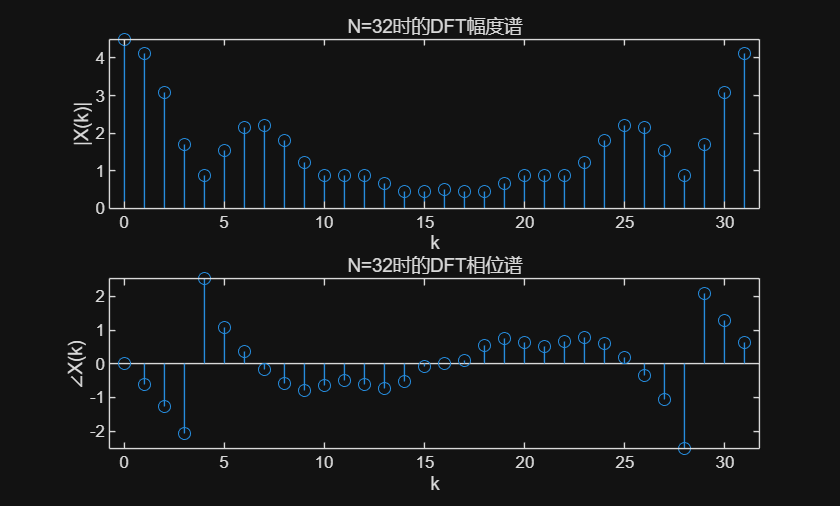

figure;
subplot(2,1,1);
stem(0:N2-1,abs(X2k));
title('N=32时的DFT幅度谱');
xlabel('k');
ylabel('|X(k)|');
subplot(2,1,2);
stem(0:N2-1,angle(X2k));
title('N=32时的DFT相位谱');
xlabel('k');
ylabel('∠X(k)');

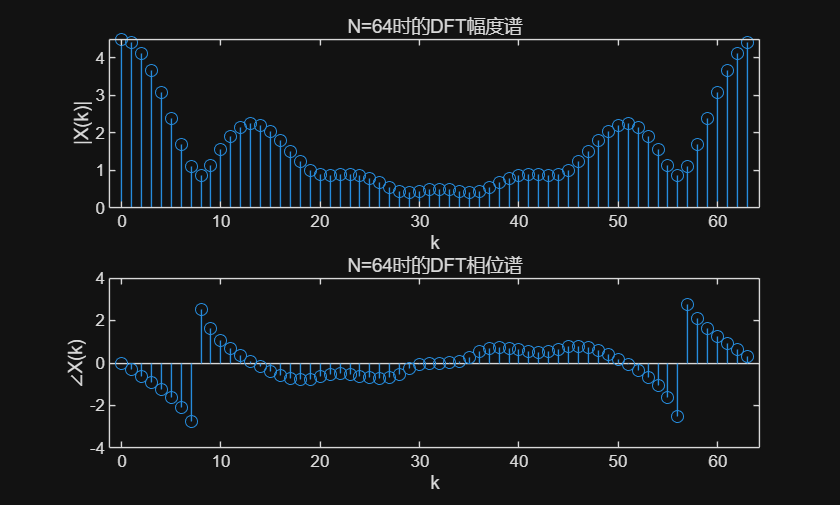

figure;
subplot(2,1,1);
stem(0:N3-1,abs(X3k));
title('N=64时的DFT幅度谱'); 
xlabel('k');
ylabel('|X(k)|');
subplot(2,1,2);
stem(0:N3-1,angle(X3k));
title('N=64时的DFT相位谱');
xlabel('k');
ylabel('∠X(k)');

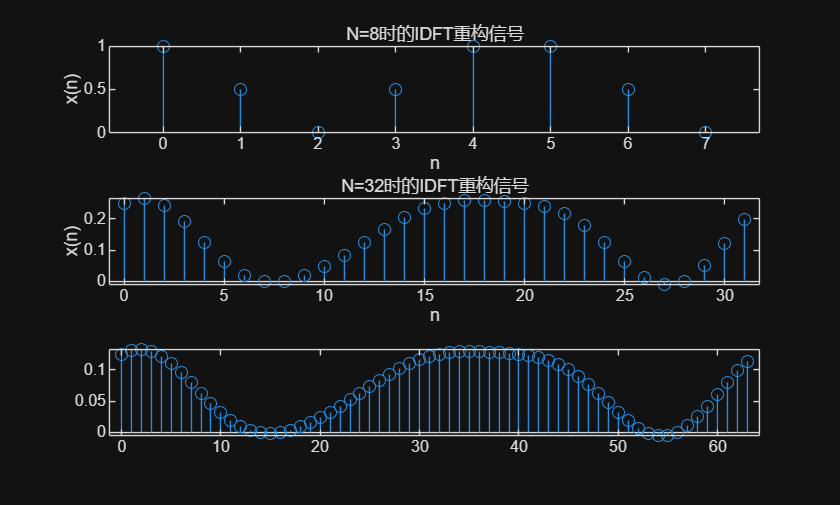

%IFFT
X1k_32 = [X1k(1 : N1/2), zeros(1, N2 - N1), X1k(N1/2 + 1 : end)];
X1k_64 = [X1k(1 : N1/2), zeros(1, N3 - N1), X1k(N1/2 + 1 : end)];
x1n_IFFT = ifft(X1k);
x2n_IFFT = ifft(X1k_32);
x3n_IFFT = ifft(X1k_64);

figure;
subplot(3,1,1);
stem(0:N1-1,real(x1n_IFFT));
title('N=8时的IDFT重构信号');
xlabel('n');
ylabel('x(n)');
subplot(3,1,2);
stem(0:N2-1,real(x2n_IFFT));
title('N=32时的IDFT重构信号');
xlabel('n');
ylabel('x(n)');
subplot(3,1,3);
stem(0:N3-1,real(x3n_IFFT));

### **题目5**：已知连续时间信号$f\left(t\right)=\textrm{sinc}\left(t\right)$，t 的取值范围为[-2,2]，请完成

### **①分别显示原连续时间信号波形（采样率100Hz，共401点）和**${F_s =10\textrm{Hz}}$况下抽样信号的波形`；`

### **②用时域卷积的方法对Fs=10Hz下获得的离散信号（41点）进行插值，（内插公式，插值核函数用9点、17点、33点长的sinc函数）重建f(t)信号（范围[-2,2]，重建后201点），并在一张图上画出重建信号和原离散信号（41点）。**

**解答5**：

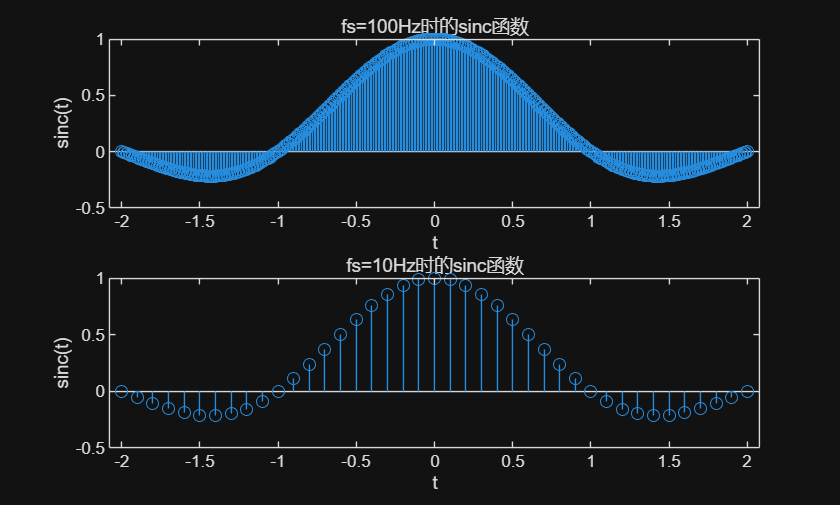

% Insert your code here
fs1 = 100;
fs2 = 10;
t1 = -2:1/fs1:2;
t2 = -2:1/fs2:2;
f1t = sinc(t1);
f2t = sinc(t2);
figure;
subplot(2,1,1);
stem(t1,f1t);
title('fs=100Hz时的sinc函数');
xlabel('t');
ylabel('sinc(t)');
subplot(2,1,2);
stem(t2,f2t);
title('fs=10Hz时的sinc函数');
xlabel('t');
ylabel('sinc(t)');

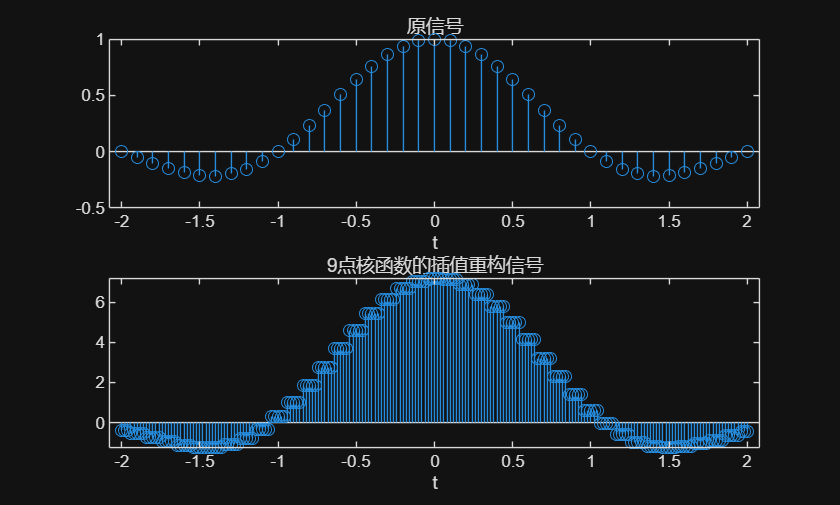

t0 = linspace(-2,2,201); %-2 2
N0 =201;
T1 = 1/fs2;
Y1 = zeros(size(t0));
L1 = 9;
K1 = (L1-1)/2; 
f2t_padded1 = [zeros(1,K1), f2t, zeros(1,K1)];%补零  000 -2  2 000 
t2_padded1 = -2-K1*T1:1/fs2:2+K1*T1;%补零后的时间轴
for i = 1:N0
    tp = t0(i);
    idx = round((tp-t2(1))/T1)+1;%对应f2t的点
    
    for j = 1:L1%j=(L1-1)/2时对应idx点
        sinc1 = sinc((j-(L1-1)/2)*T1);
        Y1(i) = Y1(i) + f2t_padded1(idx+j-1).*sinc1;
    end
end
Y2 = zeros(size(t0));
L2 = 17;
K2 = (L2-1)/2;
f2t_padded2 = [zeros(1,K2), f2t, zeros(1,K2)];
t2_padded2 = -2-K2*T1:1/fs2:2+K2*T1;
for i = 1:N0
    tp = t0(i);
    idx = round((tp-t2(1))/T1)+1;
    for j = 1:L2
        sinc2 = sinc((j-(L2-1)/2)*T1);
        Y2(i) = Y2(i) + f2t_padded2(idx+j-1).*sinc2;
    end
end

Y3 = zeros(size(t0));
L3 = 33;
K3 = (L3-1)/2;
f2t_padded3 = [zeros(1,K3), f2t, zeros(1,K3)];
t2_padded3 = -2-K3*T1:1/fs2:2+K3*T1;
for i = 1:N0
    tp = t0(i);
    idx = round((tp-t2(1))/T1)+1;
    for j = 1:L3
        sinc3 = sinc((j-(L3-1)/2)*T1);
        Y3(i) = Y3(i) + f2t_padded3(idx+j-1).*sinc3;
    end
end

figure;
subplot(2,1,1);
stem(t2,f2t);
title('原信号');
xlabel('t');
subplot(2,1,2);
stem(t0,Y1);
title('9点核函数的插值重构信号');
xlabel('t');

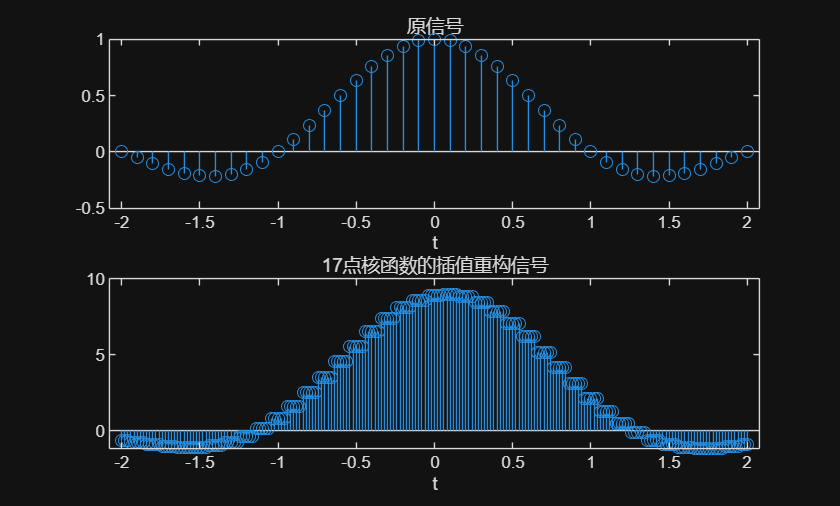

figure;
subplot(2,1,1);
stem(t2,f2t);
title('原信号');
xlabel('t');
subplot(2,1,2);
stem(t0,Y2);
title('17点核函数的插值重构信号');
xlabel('t');

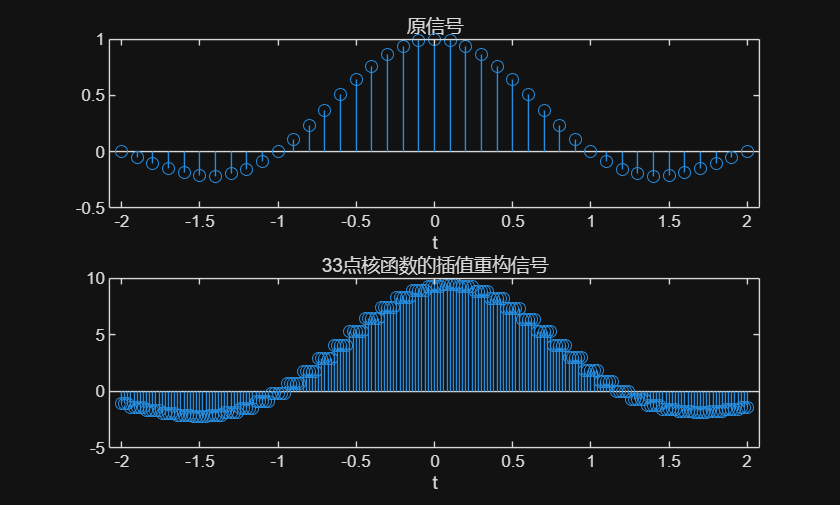

figure;
subplot(2,1,1);
stem(t2,f2t);
title('原信号');
xlabel('t');
subplot(2,1,2);
stem(t0,Y3);
title('33点核函数的插值重构信号');
xlabel('t');

### **题目6**：已知时间序列频谱为$X\left(e^{j\omega } \right)=2+4e^{-j\omega } +6e^{-\textrm{j2}\omega } +4e^{-\textrm{j3}\omega } +2e^{-\textrm{j4}\omega }$（从定义来说，x(n)=[2,4,6,4,2]），分别取频域抽样点数$N$为3、5和10,对$X\left(e^{j\omega } \right)$进行均匀采样，用IFFT计算并求出其时间序列$x\left(n\right)$，用图形显示各时间序列。由此讨论原时域信号不失真地由频域抽样恢复的条件。

**解答6**：

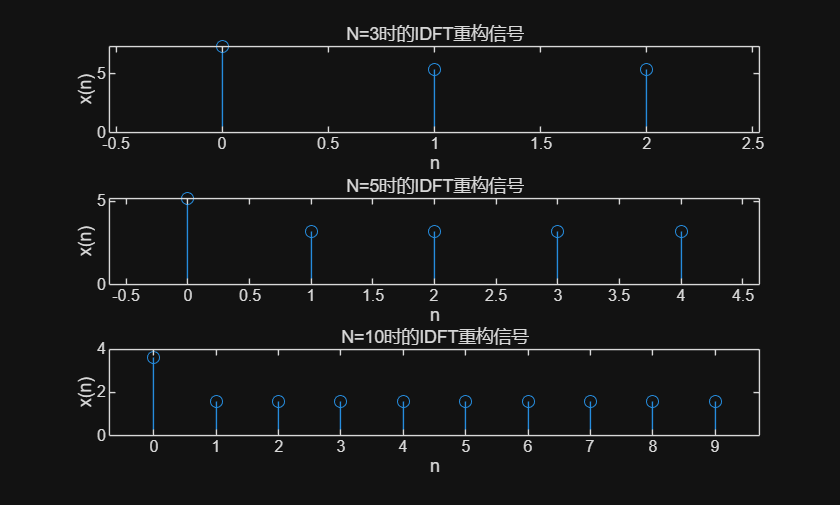

% Insert your code here
N1 = 3;
N2 = 5;
N3 = 10;
w1 = linspace(0,2*pi,N1);
w2 = linspace(0,2*pi,N2);
w3 = linspace(0,2*pi,N3);

x1w = 2+4*exp(-j*w1)+6*exp(-j*2*w1)+4*exp(-j*3*w1)+2*exp(-j*4*w1);
x2w = 2+4*exp(-j*w2)+6*exp(-j*2*w2)+4*exp(-j*3*w2)+2*exp(-j*4*w2);
x3w = 2+4*exp(-j*w3)+6*exp(-j*2*w3)+4*exp(-j*3*w3)+2*exp(-j*4*w3);

x1n = ifft(x1w);
x2n = ifft(x2w);
x3n = ifft(x3w);

figure;
subplot(3,1,1);
stem(0:N1-1,real(x1n));
title('N=3时的IDFT重构信号');
xlabel('n');
ylabel('x(n)');
subplot(3,1,2);
stem(0:N2-1,real(x2n));
title('N=5时的IDFT重构信号');
xlabel('n');
ylabel('x(n)');
subplot(3,1,3);
stem(0:N3-1,real(x3n));
title('N=10时的IDFT重构信号');
xlabel('n');
ylabel('x(n)');